## Чтение численных экспериментальных данных из XLSX

clear all
filename = 'plots_forces_moments_blood.xlsx';
sheet = 1;
%xlRange='A3:K43'; %вся таблица

%Выбор строк
RPMRange = 'A3:A43';
MassFlowRange = 'B3:B43';
PressureDeltaRange = 'C3:C43';

% MassFlowRange2 = 'B8:B43';
% PressureDeltaRange2 = 'C8:C43';
%Чтение столбцов и строк из таблицы
%subsetAll = xlsread(filename,sheet,xlRange);
RPM = xlsread(filename,sheet,RPMRange);   %Скорость вращения, [об/мин]
MassFlow = xlsread(filename,sheet,MassFlowRange);   %Массовый расход, [кг/с]
% MassFlow2 = xlsread(filename,sheet,MassFlowRange2);   %Массовый расход, [кг/с]
PressureDelta = xlsread(filename,sheet,PressureDeltaRange); %Перепад давления, [мм рт.ст.]
% PressureDelta2 = xlsread(filename,sheet,PressureDeltaRange2); %Перепад давления, [мм рт.ст.]

## Извлечение данных, согласно перепадам

RPM0 = zeros(7,1);  %задали нулевой вектор размерностью 7х1
rowCount=size(RPM,1);

for i = 6:6:size(RPM)   %заполнение его согласно таблице
    RPM0(i,1)=RPM(i,1);
end
%Взяли ненулевые значения
RPM1 = RPM0(RPM0 ~=0)

%Расход 1л/мин = 0,0175 кг/c
%RPM1 = [RPM(1) RPM(6) RPM(12) RPM(18) RPM(24) RPM(30) RPM(36)];

for j = 6:1:11 %для каждого из всех оборотов/расходов за исключением 6000 оборотов
%заполнение согласно таблице
%Инициализация
RPM0 = zeros(7,1);  

Fx0 = zeros(7,1);%задали нулевой вектор размерностью 7х1
Fy0 = Fx0;

MassFlow0 = Fx0;
PressureDelta0 = Fx0;

    for i = j:6:rowCount   % берем значения начиная с 7500 (6 ая строка)
        RPM0(i,1)=RPM(i,1);
        MassFlow0(i,1)=MassFlow(i,1);
        PressureDelta0(i,1)=PressureDelta(i,1);
    end

%Выбрали ненулевые значения зависимости от расходов (для каждого из
%расходов)
RPM_comb = RPM0(RPM0 ~= 0);

MassFlow_comb{j} = MassFlow0(MassFlow0 ~= 0);
PressureDelta_comb{j} = PressureDelta0(PressureDelta0 ~=0);
end 


% subplot(2,2,2)
% title('F_y')
xlabel('Массовый расход')
ylabel('Перепад давления, мм рт.ст.')
% legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")
% for j = 6:1:11
% %     PressureDelta_comb{j}
%     plot(MassFlow_comb{j},PressureDelta_comb{j})
% end
Q = linspace(1,6,6);
% A = MassFlow_comb{1,7}(1)
% B = PressureDelta_comb{1,7}(1)
for  j = 6:1:11
    for i = 1:6
        j1=j-5;
        MassFlow_comb_new{1,j1}(i)=MassFlow_comb{1,j}(i);
        PressureDelta_comb_new{1,j1}(i)=PressureDelta_comb{1,j}(i);
%         hold on
%         plot(MassFlow_comb{1,j}(i),PressureDelta_comb{1,j}(i),'--o')
        
    end
    
end


% PressureDelta_comb_new{1,1}(1)
% PressureDelta_comb_new{1,2}(1)
% PressureDelta_comb_new{1,3}(1)
for i = 1:6
    for j = 1:6
    PressDelt{j,i} = PressureDelta_comb_new{1,i}(j);
    MassFl{j,i} = MassFlow_comb_new{1,i}(j);
%     PressDelt{2,i} = PressureDelta_comb_new{1,i}(2)
    end
end
PD = cell2mat(PressDelt)
MFL = cell2mat(MassFl)
for i=1:6
    hold on
    plot(Q,PD(i,:))
    % Интерполировать по расходу
    
end
save('deltaPressureFlow.mat', "PD","MFL","Q")


clear all
load('deltaPressureFlow.mat');
% xData_save = zeros(6);
% yData_save = zeros(6);
for i=1:6

%     legend({'7500','9000','10500','12000','13500','15000'},"Location","best")
%     plot(Q,PD(i,:))
%     hold off
i
    xlabel(' л/мин')
    ylabel('Перепад давления')
    % Интерполировать по расходу и по перепадам давления
    [xData, yData] = prepareCurveData( Q, PD(i,:) );
    % Set up fittype and options.
% ft = fittype( 'cubicinterp' );
ft{i} = fittype('poly2');
% opts = fitoptions( 'Method','CubicSplineInterpolant');
% % opts.Display = 'Off';
% opts.Normalize = 'on';
% % opts.StartPoint = [0 0 0 2.17655923708106];

% Fit model to data.
[fitresult{i}, gof] = fit( xData, yData, ft{i} );
% hold on
% Plot fit with data.
figure( 'Name', 'FIT' );
%  xData_save(i) = xData; %6x1
yData_save{i} = yData; %6x1
h{i} = plot( fitresult{i}, xData, yData);
% legend( h, 'PD vs. MFL', 'FourierFit1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% % Label axes
% xlabel( 'MFL', 'Interpreter', 'none' );
% ylabel( 'PD', 'Interpreter', 'none' );
grid on
end

save('fittedResult.mat',"yData_save","fitresult","xData");

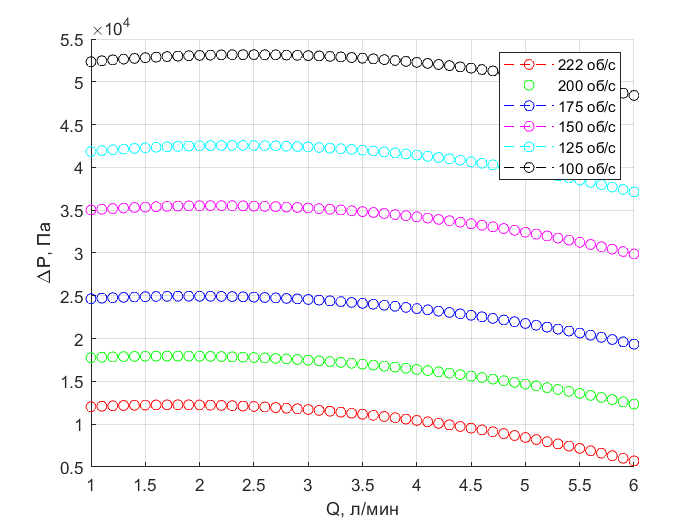

x = 1

x = 1.1000

x = 1.2000

x = 1.3000

x = 1.4000

x = 1.5000

x = 1.6000

x = 1.7000

x = 1.8000

x = 1.9000

x = 2

x = 2.1000

x = 2.2000

x = 2.3000

x = 2.4000

x = 2.5000

x = 2.6000

x = 2.7000

x = 2.8000

x = 2.9000

x = 3

x = 3.1000

x = 3.2000

x = 3.3000

x = 3.4000

x = 3.5000

x = 3.6000

x = 3.7000

x = 3.8000

x = 3.9000

x = 4

x = 4.1000

x = 4.2000

x = 4.3000

x = 4.4000

x = 4.5000

x = 4.6000

x = 4.7000

x = 4.8000

x = 4.9000

x = 5

x = 5.1000

x = 5.2000

x = 5.3000

x = 5.4000

x = 5.5000

x = 5.6000

x = 5.7000

x = 5.8000

x = 5.9000

x = 6

clear all
clear clc
clf
load('fittedResult.mat');
% for i=1:6
%     i
%     hold on
%     plot(fitresult{i},xData,yData_save{i});
% %     plot(fitresult{i},yData_save{i},xData);
%     grid on  
%     hold off    
% end
yDataArr = cell2mat(yData_save); %6x6
xDataArr = zeros(6);
for i =1:6
xDataArr(:,i) = xData;   
end

% a=1*1,666666666666667e-5;
% b=6*1,666666666666667e-5;
N = linspace(1,6,50); %Число моментов времени
for x=1:0.1:6 %варьировать в пределах от 1 до 6 л/мин
%     1 л = 1 дм³ = 0,001 м³ 
%     1 мин = 60 с
%  1л/мин = 1*0.001/60
%     x=uint8(x);
%     fitCurve1(x) = -2.746*x^2+9.723*x+83.39;
x=x*1,666666666666667E-5;
% Уже интерполированные кривые аналитически заданные, снимаем значения
[fitCurve1,fitCurve2,fitCurve3,fitCurve4,fitCurve5,fitCurve6] = fitDeltaPress(x);
fitCurve1=fitCurve1*133.3224; %Перевод мм рт ст в Па;
fitCurve2=fitCurve2*133.3224;
fitCurve3=fitCurve3*133.3224;
fitCurve4=fitCurve4*133.3224;
fitCurve5=fitCurve5*133.3224;
fitCurve6=fitCurve6*133.3224;

%     fitCurveSave{1,x}=fitCurve1;
%     fitCurveSave{2,x}=fitCurve2;
%     fitCurveSave{3,x}=fitCurve3;
%     fitCurveSave{4,x}=fitCurve4;
%     fitCurveSave{5,x}=fitCurve5;
%     fitCurveSave{6,x}=fitCurve6;

% figure 
    hold on
    plot(x,fitCurve1,'--or');
    plot(x,fitCurve2,'og');
    plot(x,fitCurve3,'--ob');
    plot(x,fitCurve4,'--om');
    plot(x,fitCurve5,'--oc');
    plot(x,fitCurve6,'--ok');
    legend('222 об/с', '200 об/c','175 об/c','150 об/c','125 об/c','100 об/c')
    xlabel('Q, л/мин');
    ylabel('\DeltaP, Па')
    grid on  
    hold off  
end


N=5

N = 5

N=5*1,666666666666667E-5;

N = 5

[fitCurve1,fitCurve2,fitCurve3,fitCurve4,fitCurve5,fitCurve6] = fitDeltaPress(N);
fitCurve1=fitCurve1*133.3224; %Перевод мм рт ст в Па;
fitCurve2=fitCurve2*133.3224;
fitCurve3=fitCurve3*133.3224;
fitCurve4=fitCurve4*133.3224;
fitCurve5=fitCurve5*133.3224;
fitCurve6=fitCurve6*133.3224;
figure   
hold on  
N=5*1,666666666666667E-5;

N = 5

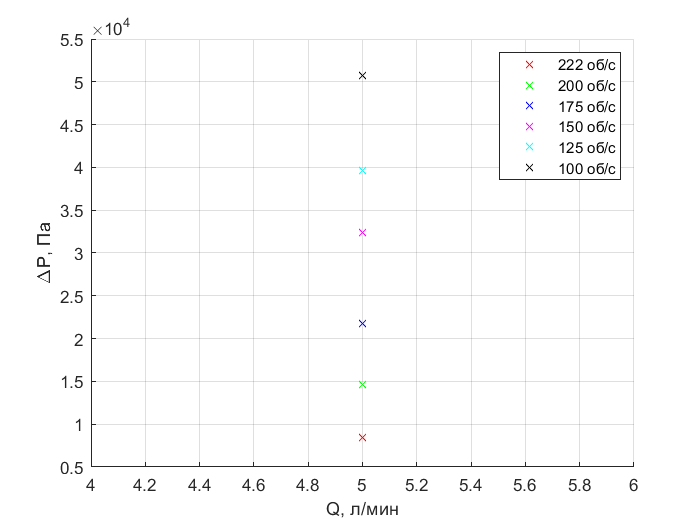

plot(N,fitCurve1,'xr');

    plot(N,fitCurve2,'xg');
    plot(N,fitCurve3,'xb');
    plot(N,fitCurve4,'xm');
    plot(N,fitCurve5,'xc');
    plot(N,fitCurve6,'xk');
    legend('222 об/с', '200 об/c','175 об/c','150 об/c','125 об/c','100 об/c')
xlabel('Q, л/мин');
ylabel('\DeltaP, Па')
        grid on  
     hold off 

% delta.max = 
fitCurve1

fitCurve1 = 8.4466e+03

fitCurve6

fitCurve6 = 5.0723e+04

delta.max=[N; fitCurve6];
delta.min=[N; fitCurve1];
fitCurveBetween = linspace(fitCurve1,fitCurve3);

% T=linspace(0,10);
% % deltaP = 130*sin(T)+178;
% mean1 = ((fitCurve6+fitCurve1)/2);
% mean2 = ((fitCurve6-fitCurve1)/2);
% square1 = sqrt(fitCurve1^2+fitCurve6^2);
% mean3 = (mean1+mean2)/2;
%  deltaP = 110*sin(T)+mean3;
% plot(T,deltaP)
% xlabel('t, с')
% ylabel('\DeltaP, мм рт.ст.')
% grid on


Речь идет об обыкновенной интерполяции гармоническим рядом

(можно говорить и об аппроксимации)

**Надо взять реальную запись p(t).**

s(t)=p(t)-mean(p(t))     - среднее

t_1<=t<=t_n (n=2N+1),

будем иметь s(t_i)

T=t_n-t_1,w=2*pi/T

S=suuma(a_j*cos(j*w*t)+b_j*sin()), j=1….N

Методом наим. кв. находим a, b

## **Реальная запись p(t) из статьи**

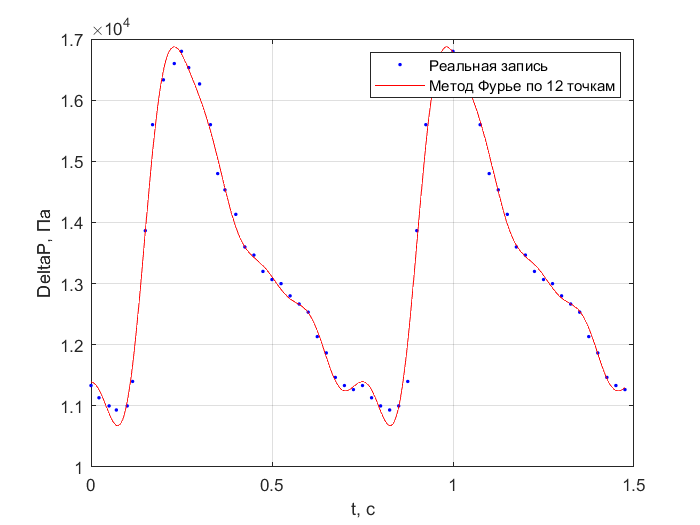

ft =      General model Fourier5:
     ft(x) =  a0 + a1*cos(x*w) + b1*sin(x*w) + 
               a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + 
               a4*cos(4*x*w) + b4*sin(4*x*w) + a5*cos(5*x*w) + b5*sin(5*x*w)
       where x is normalized by mean 0.7371 and std 0.4371
     Coefficients (with 95% confidence bounds):
       a0 =   1.335e+04  (1.33e+04, 1.339e+04)
       a1 =       -2152  (-2220, -2084)
       b1 =       969.8  (901.1, 1038)
       a2 =      -472.1  (-542.7, -401.5)
       b2 =       -1095  (-1163, -1027)
       a3 =       470.5  (401.5, 539.4)
       b3 =       -94.2  (-164.6, -23.84)
       a4 =       203.9  (136.1, 271.6)
       b4 =       238.9  (169.5, 308.3)
       a5 =      -27.93  (-96.82, 40.97)
       b5 =       200.9  (133.3, 268.5)
       w =       3.648  (3.628, 3.668)

gof = struct with fields:
           sse: 1.6499e+06
       rsquare: 0.9926
           dfe: 48
    adjrsquare: 0.9909
          rmse: 185.4000


press.aortic = [85 83.5 82.5 82 82.5 85.5 104 117 122.5 124.5 126 124 122 117 111 109 106 102 101 99 98 97.5 96 95 94 91 89 86 85 84.5 85 83.5 82.5 82 82.5 85.5 104 117 122.5 124.5 126 124 122 117 111 109 106 102 101 99 98 97.5 96 95 94 91 89 86 85 84.5]; %мм рт.ст.
time.aortic = [0 22 50 70 100 115 150 170 200 230 250 270 300 330 350 370 400 425 450 475 500 525 550 575 600 625 650 675 700 725 750 775 800 825 850 875 900 925 950 975 1000 1025 1050 1075 1100 1125 1150 1175 1200 1225 1250 1275 1300 1325 1350 1375 1400 1425 1450 1475 ]; %ms
press.aortic2 = [85 83.5 82.5 82 82.5 85.5 104 117 122.5 124.5 126 124 122 117 111 109 106 102 101 99 98 97.5 96 95 94 91 89 86 85 84.5]; %мм рт.ст.
time.aortic2 =[0 22 50 70 100 115 150 170 200 230 250 270 300 330 350 370 400 425 450 475 500 525 550 575 600 625 650 675 700 725]; %ms
% plot(time.aortic, press.aortic, 'x')
AorticPressure = press.aortic*133.3224; %Перевод мм рт ст в Па;;
AorticTime = time.aortic/1000; %Перевод мс в с;
% [ft,gof]=AorticFit(time.aortic,press.aortic)
[ft,gof]=FourierFit5Normalized(time.aortic,press.aortic)

`ft = `

`     General model Fourier5:`

`     ft(x) =  a0 + a1*cos(x*w) + b1*sin(x*w) + `

`               a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + `

`               a4*cos(4*x*w) + b4*sin(4*x*w) + a5*cos(5*x*w) + b5*sin(5*x*w)`

`     Coefficients (with 95% confidence bounds):`

`       a0 =       100.1  (99.73, 100.5)`

`       a1 =      -15.05  (-15.62, -14.47)`

`       b1 =        9.33  (8.655, 10)`

`       a2 =      -5.557  (-6.175, -4.939)`

`       b2 =       -7.01  (-7.61, -6.409)`

`       a3 =       2.985  (2.472, 3.498)`

`       b3 =       -2.01  (-2.569, -1.451)`

`       a4 =       2.223  (1.694, 2.752)`

`       b4 =      0.7806  (0.2274, 1.334)`

`       a5 =      0.7561  (0.2104, 1.302)`

`       b5 =        1.32  (0.8004, 1.84)`

`       w =    0.008345  (0.0083, 0.008391)`

`     General model Fourier5_NORMALIZED:`

`     ft(x) =  a0 + a1*cos(x*w) + b1*sin(x*w) + `

`               a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + `

`               a4*cos(4*x*w) + b4*sin(4*x*w) + a5*cos(5*x*w) + b5*sin(5*x*w)`

`       where x is normalized by mean 737.1 and std 437.1`

`     Coefficients (with 95% confidence bounds):`

`       a0 =       100.1  (99.73, 100.5)`

`       a1 =      -16.14  (-16.65, -15.63)`

`       b1 =       7.274  (6.759, 7.789)`

`       a2 =      -3.541  (-4.071, -3.012)`

`       b2 =      -8.214  (-8.723, -7.705)`

`       a3 =       3.529  (3.012, 4.046)`

`       b3 =     -0.7066  (-1.234, -0.1788)`

`       a4 =       1.529  (1.021, 2.038)`

`       b4 =       1.792  (1.271, 2.313)`

`       a5 =     -0.2095  (-0.7262, 0.3073)`

`       b5 =       1.507  (1, 2.014)`

`       w =       3.648  (3.628, 3.668)`

s(t)=p(t)-mean(p(t))     - среднее

t_1<=t<=t_n (n=2N+1),

будем иметь s(t_i)

T=t_n-t_1,w=2*pi/T

S=suuma(a_j*cos(j*w*t)+b_j*sin()), j=1….N

Методом наим. кв. находим a, b

Фурье 4ого рода + М.Н.К.

       a0 =       100.1 ;
       a1 =      -15.04 ;
       b1 =       9.312  ;
       a2 =      -5.534  ;
       b2 =       -6.99  ;
       a3 =       2.958  ;
       b3 =      -2.019  ;
       a4 =        2.26  ;
       b4 =      0.7604  ;
       w =    0.008345  ;
       

Фурье 5ого рода.

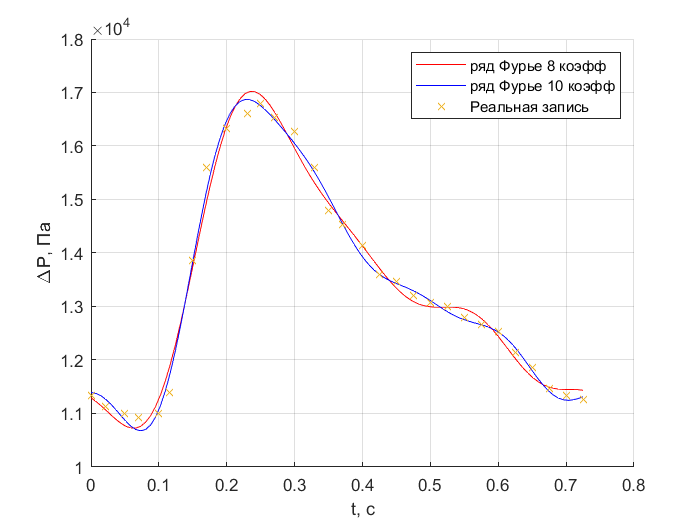

       
       a0=100.1;
       a1=-15.05;
       b1=9.33;
       a2=-5.557;
       b2=-7.01;
       a3=2.985;
       b3=-2.01;
       a4= 2.223;
       b4 =0.7806;
       a5 =0.7561;
       b5 =1.32;
       w = 0.008345;
       
period = 1;
x=linspace(0,725*period);
x2=x/1000; %Перевод мс в с
p.t2 =  a0 + a1*cos(x*w) + b1*sin(x*w) + a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + a4*cos(4*x*w) + b4*sin(4*x*w);
p.t3 = a0 + a1*cos(x*w) + b1*sin(x*w) + a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) +  a4*cos(4*x*w) + b4*sin(4*x*w) + a5*cos(5*x*w) + b5*sin(5*x*w);
% press.aortic2 = [85 83.5 82.5 82 82.5 85.5 104 117 122.5 124.5 126 124 122 117 111 109 106 102 101 99 98 97.5 96 95 94 91 89 86 85 84.5]; %мм рт.ст.
% time.aortic2 =[0 22 50 70 100 115 150 170 200 230 250 270 300 330 350 370 400 425 450 475 500 525 550 575 600 625 650 675 700 725]; %ms
p.t4=p.t2*133.3224; %Перевод мм рт ст в Па
p.t5=p.t3*133.3224; %Перевод мм рт ст в Па
time.aortic3=time.aortic2/1000;
press.aortic3=press.aortic2*133.3224;
figure
hold on
plot(x2,p.t4, 'r');
plot(x2,p.t5,'b');

plot(time.aortic3,press.aortic3,'x');

grid on
xlabel('t, с');
ylabel('\DeltaP, Па')
legend('ряд Фурье 8 коэфф', 'ряд Фурье 10 коэфф', 'Реальная запись')
% legend( 'Аппроксимация', 'Реальная запись')
% 82-126
% for N=1:6 %расходы
%     [fitCurve1,fitCurve2,fitCurve3,fitCurve4,fitCurve5,fitCurve6] = fitDeltaPress(N);
%     fitCurveBetween = linspace(fitCurve1,fitCurve6);
%     
%     if ((fitCurve1-p.t2)<3)
%     mserr1(N) = fitCurve1;
% %     mserr2 = fitCurve2
% 
%     plot(N,mserr1,'x')
%     end
%     if fitCurve2-p.t2<20
%         mserr2(N) = fitCurve2;
%     end
% end
hold off

save("fitcurveData.mat")

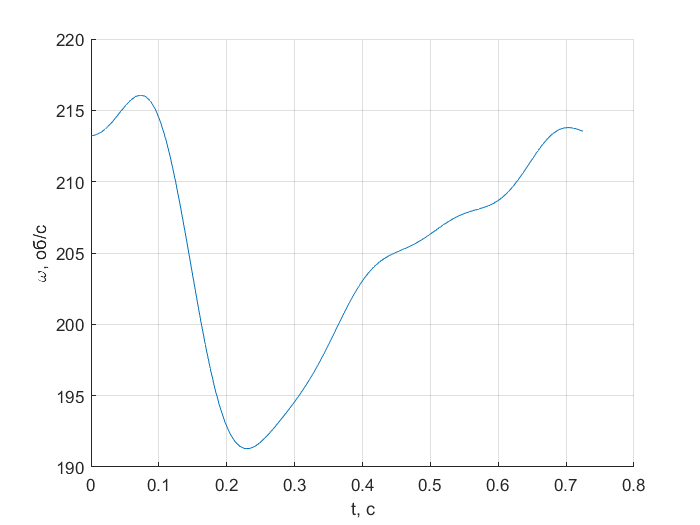

clf
load("fitcurveData.mat")
figure("Name",'Изменение скорости вращения ротора в течение сердечного цикла, обеспечивающее пульсации в аорте, близкие к физиологическим ')
om1 = 225;
om2 = 200;
om3 = 175;
f = om1 + (om2+om1)*(p.t3+fitCurve1)/(fitCurve2-fitCurve1);
f2 = om1 + (om3-om1)*(p.t3-fitCurve1)/(fitCurve3-fitCurve1);
f3 = om1 + (om2-om1)*(p.t5-fitCurve1)/(fitCurve2-fitCurve1);
hold on
% plot(x,f)
plot(x2,f3)
xlabel('t, с');
ylabel('\omega, об/с')
% legend('Изменение скорости вращения ротора')
% legend('n_1+(n_2+n_1)*(p+p_1)/(p_2-p_1)','n_1+(n_2-n_1)*(p-p_1)/(p_2-p_1)' )
grid on
hold off

%Построение графика мощностей P=M*n
% P(t) = M(t)*n(t)
load("FplusM.mat")

% % Ввод частоты, расхода - получение значения силы
% % задаем расход (ячека определяет проекцию вектора и расход,
% % первый индекс m = 1 - Fx, m=2 - Fy, m=3 - Fz, m=4 - Fr, m=5 - Mx и т.д. m=8 - Mr аналогично,
% % второй индекс n = 1 - расход 1 л/мин, n=6 - расход 6 л/мин

% prompt = 'Выберите величину для поиска Fx, Fy, Fz, Fr, Mx, My, Mz, Mr ?:';
% str = input(prompt, 's');
% if isempty(str)
%     str = 'Fx';
%     m=1;
%     FM_flag=1; % Флаг это сила или момент? 1 - сила, 2 - момент
% elseif str == "Fx"
%     m=1;
%     FM_flag=1;
% elseif str == "Fy"
%     m=2;
%     FM_flag=1;
% elseif str == "Fz"
%     m=3;
%     FM_flag=1;
% elseif str == "Fr"
%     m=4;
%     FM_flag=1;
% elseif str == "Mx"
%     m=5
%     FM_flag=2;
% elseif str == "My"
%     m=6;
%     FM_flag=2;
% elseif str == "Mz"
%     m=7;
%     FM_flag=2;
% elseif str == "Mr"
%     m=8;
%     FM_flag=2;
% end

m=7; %Mz
n=5; % Расход
FM_flag=0; % не строим график если = 0

% prompt = 'Значение требуемого расхода от 1 до 6:';
% n = input(prompt);
% if isempty(n)
%     n=1;
% end

% % m = 1; % выбор величины для поиска 1-4 = силы, 5-8 = моменты, см. выше
% % n=1; % расход в л/мин по шкале от 1 до 6
% 
% % Простое задание частоты вращения в об/мин в пределах от 7500 до 15000
% % RPMtofind = 9500;

% x2 - время, f3 - частоты, прогоняемся по всем частотам
% Затем вычисляем значение момента Mz от каждой частоты, схороняем
Mzet= zeros(2, 100, 'double');
% Переведем частоту обратно с об/с в об/мин
f3_min = f3*60;
% hold on

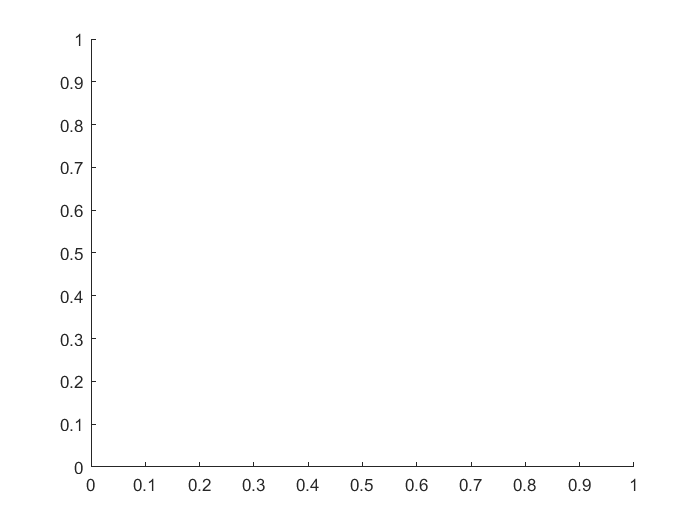

iter =  1;
for freq=f3_min

    RPMtofind = freq;
RPMtofind;

% prompt = 'Значение частоты от 7500 до 15000 об/мин:';
% RPMtofind = input(prompt);
% if isempty(RPMtofind)
%     RPMtofind=7500;
% end

plotdata = FplusM{m,n}; 
% figure

% Получаем значение силы на заданной частоте
ForceOrMoment = getForceOnRPMandFlow(RPM_comb,plotdata,RPMtofind,FM_flag);
Mzet(1,iter)=ForceOrMoment;
iter = iter+1;
% Сохранить все значения Mz(n) и построить график
end
% hold off

Mzet(2,:)=x2; % Время
save('findingM_(t).mat')

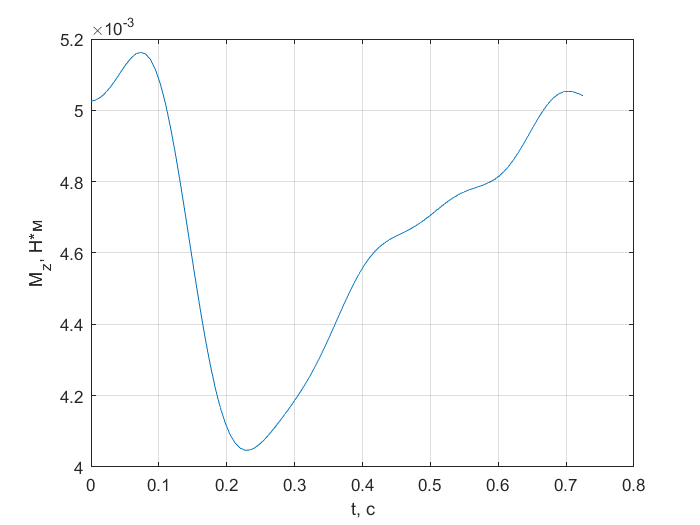

load('findingM_(t).mat')
figure
plot(Mzet(2,:), Mzet(1,:))
xlabel('t, с');
ylabel('M_z, Н*м')
grid on

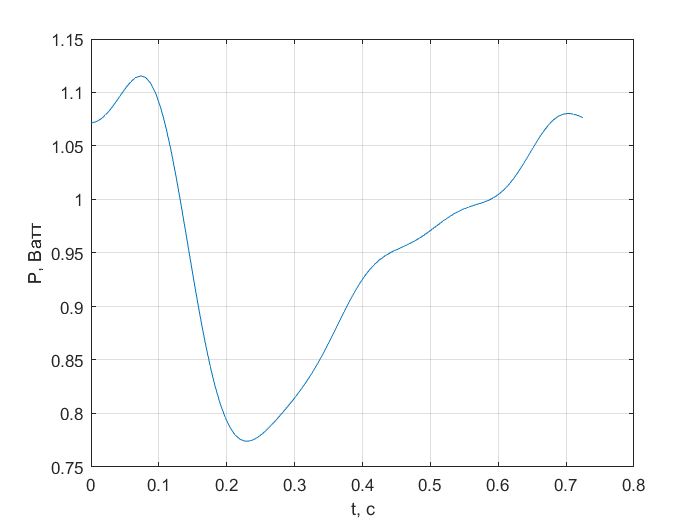

figure("Name","График мощности во времени")
P_power = Mzet(1,:).*f3;
plot(x2,P_power)
xlabel('t, с');
ylabel('P, Ватт')
grid on